N_sim = 100;

untruncated = makedist('Normal',1,0.01);
truncated = truncate(untruncated,0.8,1.2);
D = random(truncated,N_sim,1);
mean(D)

ans = 1.0004

std(D)

ans = 0.0089

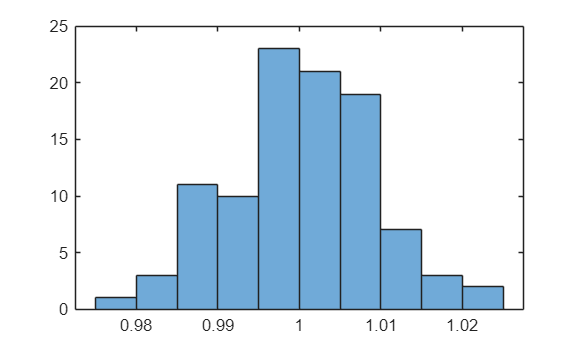

histogram(D)

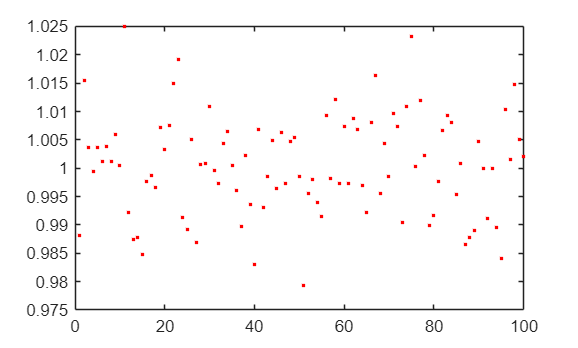

plot(D,'r.')


save(['Dw_K',num2str(N_sim),'.mat'],'D')


a = 1.6; b = 2.4; k = 100;
alpha = 2*k; beta = 4*k;
untruncated = makedist('Beta','a',alpha,'b',beta);
mu = a + (b-a)*random(untruncated,N_sim,1);
Mean =mean(mu)

Mean = 1.8681

Mean_theo = a + (b-a)*alpha/(alpha+beta)

Mean_theo = 1.8667

Std = std(mu)

Std = 0.0167

Std_theo = (b-a)*sqrt(alpha*beta/((alpha+beta)^2*(alpha+beta+1)))

Std_theo = 0.0154

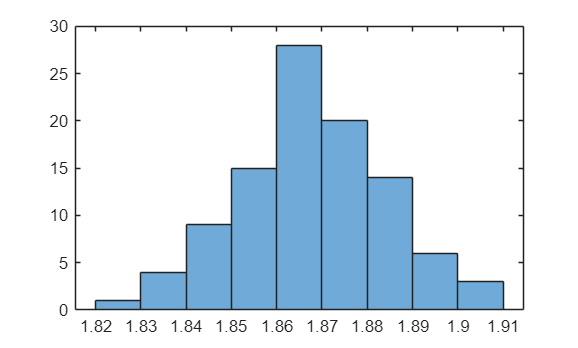


histogram(mu)

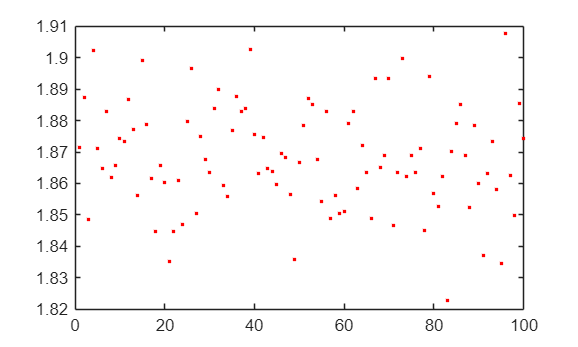

plot(mu,'r.')

filename = ['muw_K',num2str(N_sim),'.mat']

filename = 'muw_K100.mat'

save(filename,'mu')